# Answers

## Question 1:

## According to the results you found, does the estimated model describe well the manipulator system? Motivate the answer

% MSE = Mean Squared Error
MSE = zeros(size(PARAM, 1), 1);
for i = 1:numel(PARAM)
    values = PARAM{i}; 
    y_hat_2 = g_map(y1, x2, x1, values("beta"), values("lambda"), sigma_square);
    error = y_hat_2-y2;
    MSE(i) = (transpose(error)*error) / N;
end
MSE

MSE =     0.7011
   11.4565
    3.2817


## Question 2:

## According to the results you found, which is the role of λ and β?

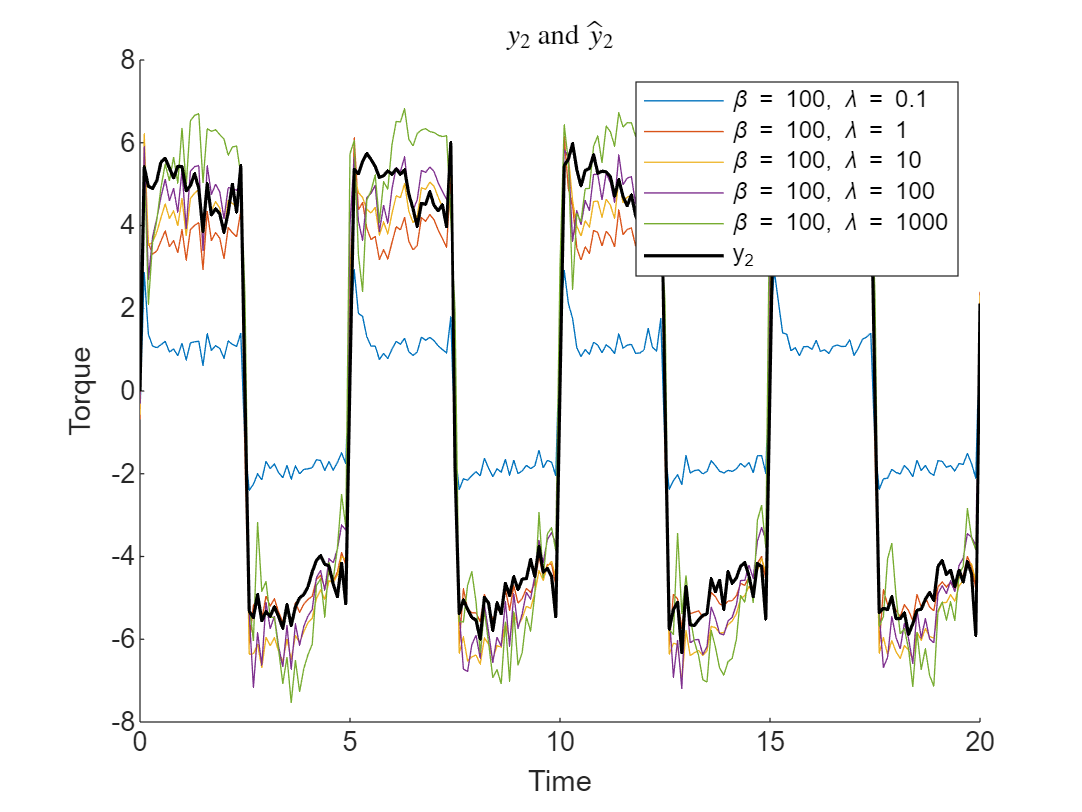


% Role of Lambda
LAMBDA_COLLECTION = {
    dictionary(["lambda","beta"], [0.1,  100]);
    dictionary(["lambda","beta"], [1,    100]);
    dictionary(["lambda","beta"], [10,   100]);
    dictionary(["lambda","beta"], [100,  100]);
    dictionary(["lambda","beta"], [1000, 100]);
};
figure; hold on;
for i = 1:numel(LAMBDA_COLLECTION)
    values = LAMBDA_COLLECTION{i}; 
    y_hat_2 = g_map(y1, x2, x1, values("beta"), values("lambda"), sigma_square);
    plot(t, y_hat_2, 'DisplayName', ...
        "\beta = " + values("beta") + ", \lambda = " + values("lambda"));
end
plot(t, y2, 'k', 'LineWidth', 1.2, 'DisplayName', 'y_2');
legend show;
xlabel('Time');
ylabel('Torque');
title('$y_2$ and $\hat{y}_2$', 'Interpreter', 'latex');

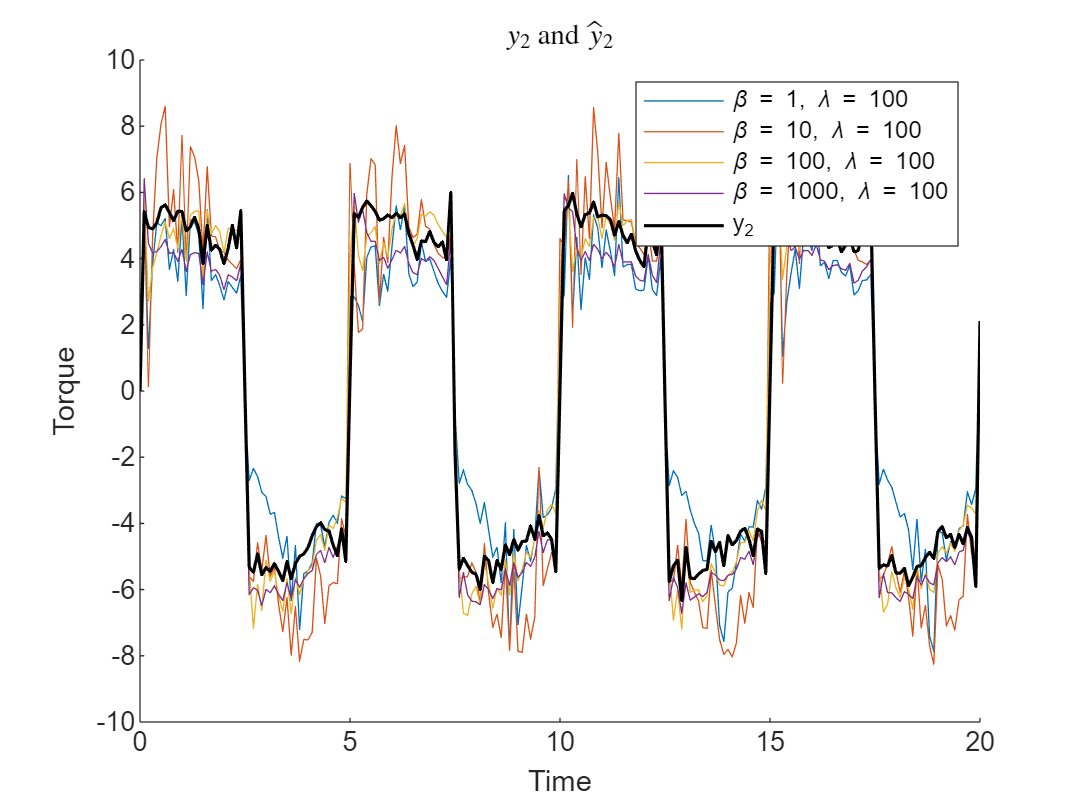


% Role of Beta
BETA_COLLECTION = {
    dictionary(["lambda","beta"], [100,    1]);
    dictionary(["lambda","beta"], [100,   10]);
    dictionary(["lambda","beta"], [100,  100]);
    dictionary(["lambda","beta"], [100, 1000]);
};
figure; hold on;
for i = 1:numel(BETA_COLLECTION)
    values = BETA_COLLECTION{i}; 
    y_hat_2 = g_map(y1, x2, x1, values("beta"), values("lambda"), sigma_square);
    plot(t, y_hat_2, 'DisplayName', ...
        "\beta = " + values("beta") + ", \lambda = " + values("lambda"));
end
plot(t, y2, 'k', 'LineWidth', 1.2, 'DisplayName', 'y_2');
legend show;
xlabel('Time');
ylabel('Torque');
title('$y_2$ and $\hat{y}_2$', 'Interpreter', 'latex');

## Question 3)

PARAM = {
    dictionary(["lambda","beta"], [10,  100]);
    dictionary(["lambda","beta"], [0.1, 100]);
    dictionary(["lambda","beta"], [10,  1]);
};

yf_matrix = zeros(size(w, 1), numel(PARAM));
for i = 1:numel(PARAM)
    values = PARAM{i}; 
    yf_matrix(:,i) = g_map(y1, xf, x1, values("beta"), values("lambda"), sigma_square);
end

## Functions

function  y_hat = g_map(y1, x, x1, beta, lambda, sigma_square)
    y_hat = lambda*Cauchy_kernel(x, x1, beta)*inv(lambda*Cauchy_kernel(x1, x1, beta)+ ...
            sigma_square*eye(size(x1, 1)))*y1;
end